clc; clear all; close all; 

% MODEL
%  7   --   8   --   9
%  |        |        |
%  |   3    |   4    |
%  4   --   5   --   6
%  |        |        |
%  |   1    |   2    |
%  1   --   2   --   3
%
% ELEMENT
%  4   --   3 
%  |        |
%  |        | 
%  1   --   2

% Given parameters
lx_1 = 0.8; lx_2 = 1.2;
ly_1 = 1.0; ly_2 = 1.4;

% Material
E = 2.1e5;
nu = 0.3;
C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0, 0, (1 - nu) / 2];

% Set up nodes and elements
% GLOBAL nodes
nodes = [0, 0;
         lx_1, 0;
         lx_1+lx_2, 0;

         0, ly_1;
         lx_1, ly_1;
         lx_1+lx_2, ly_1;
         
         0, ly_1+ly_2;
         lx_1, ly_1+ly_2;
         lx_1+lx_2, ly_1+ly_2];

% Nodal indices per element
% LOCAL -> GLOBAL
elements = [1 2 5 4;
            2 3 6 5;
            4 5 8 7;
            5 6 9 8];


nNodes = size(nodes, 1);
dofPerNode = 2;
nElements = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement = dofPerNode * nodesPerElement;

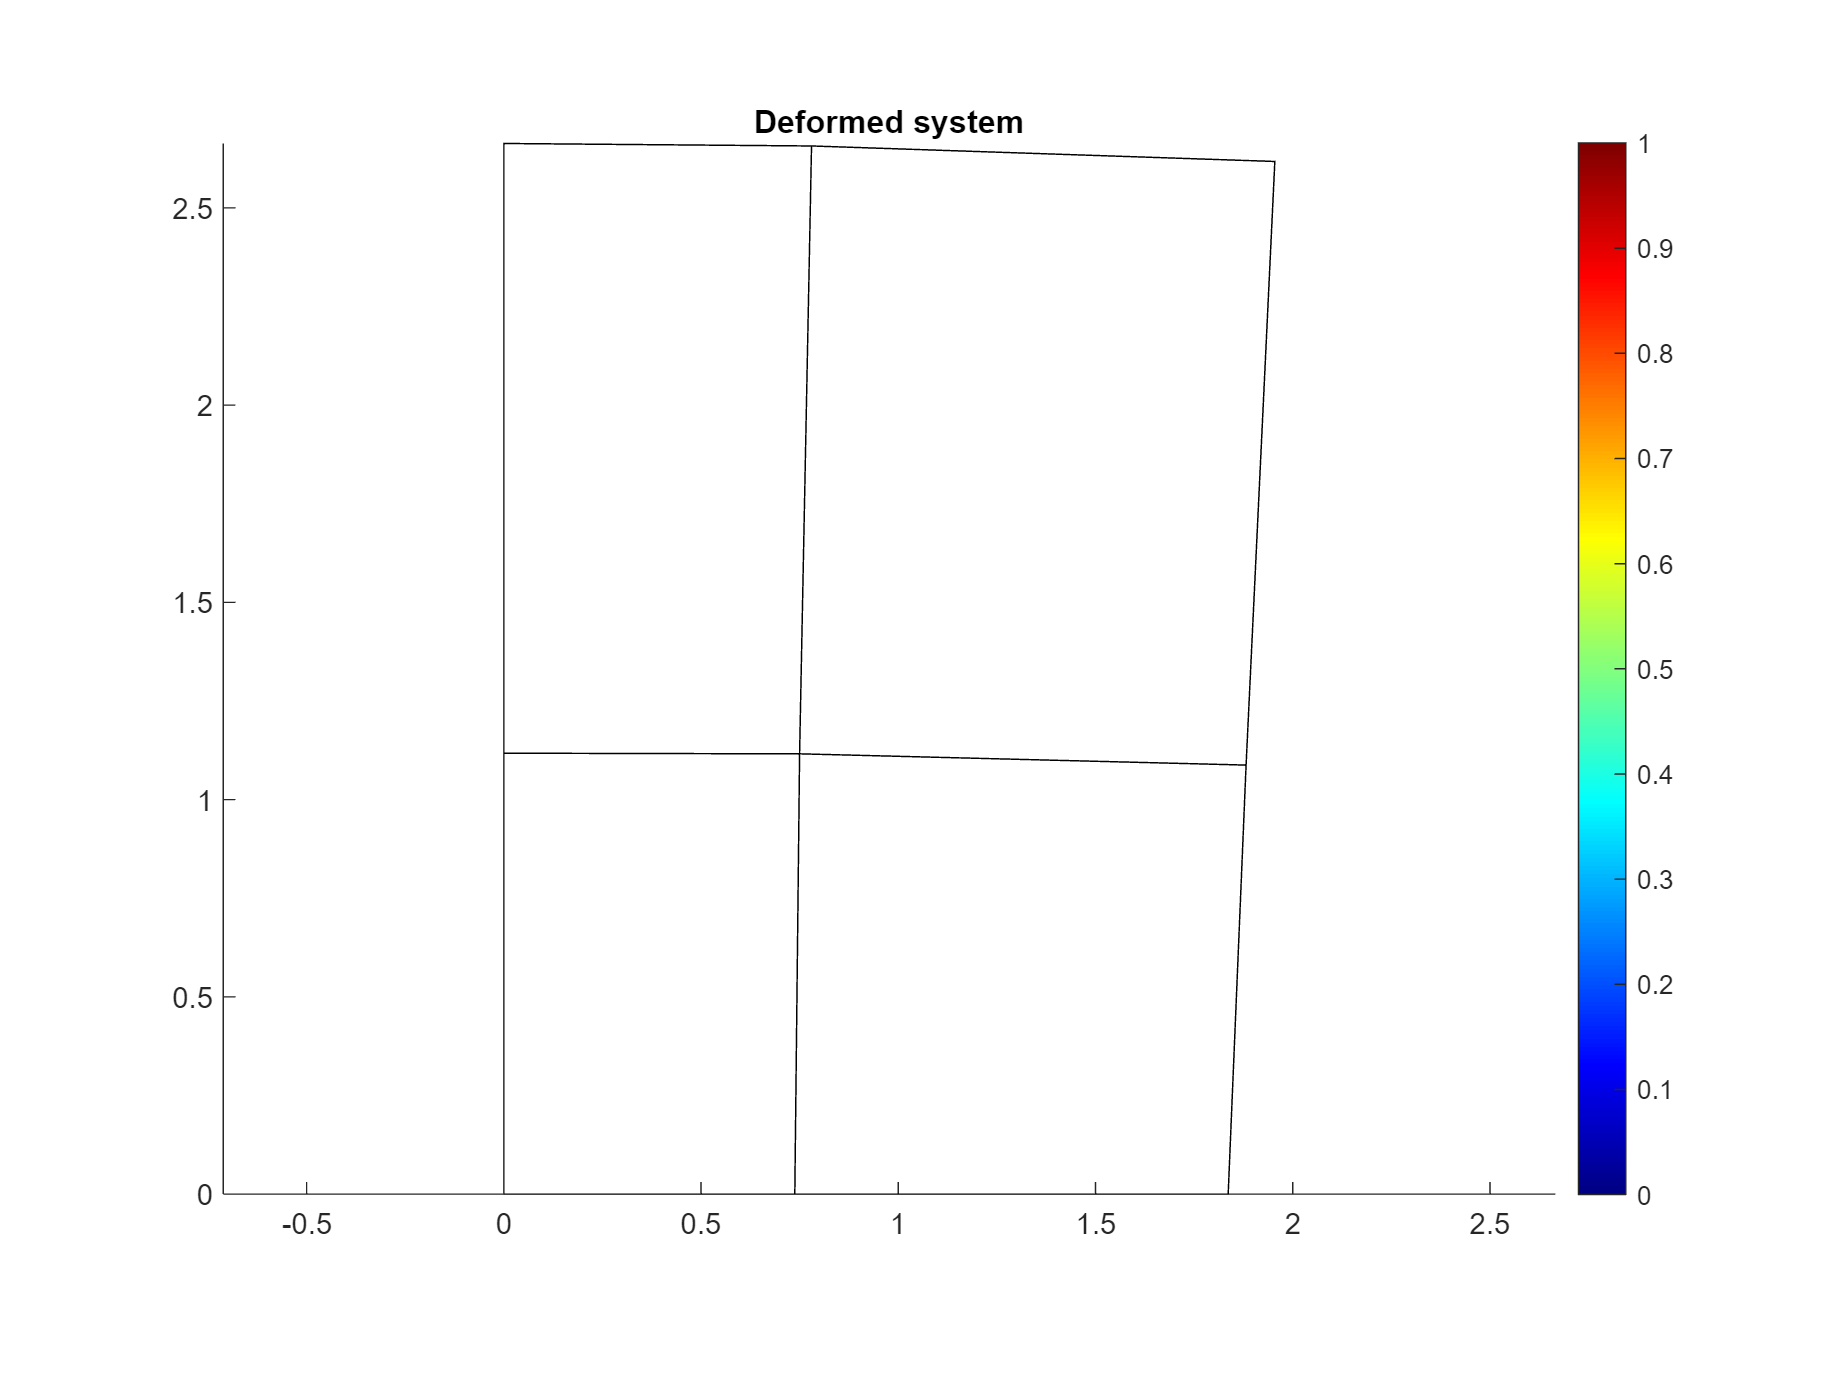

% Set up system matrices
K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);


% Integrate stiffness by looping over elements
[xg, wg] = gaussianPoints2D(2);
for e = 1 : nElements
    KE = zeros(dofPerElement);
    fE = zeros(dofPerElement, 1);

    % Get element corner coordinates
    xmin = nodes(elements(e, 1),1);
    xmax = nodes(elements(e, 2),1);
    ymin = nodes(elements(e, 1),2);
    ymax = nodes(elements(e, 4),2);

    % Integrate stiffness using Gauss quadrature
    for g = 1 : size(xg, 1)
        % Map integration point from standard space (r, s) to cartesian coordinates (x, y)
        xgi(1) = 0.5 * (xmax - xmin) * xg(g, 1) + 0.5 * (xmax + xmin);
        xgi(2) = 0.5 * (ymax - ymin) * xg(g, 2) + 0.5 * (ymax + ymin);

        % Get B matrix for stiffness integration
        B = bMatrix(xmin, xmax, ymin, ymax, xgi);

        % Evaluate summand for quadrature of element stiffness matrix
        KE = KE + B' * C * B * wg(g);
    end
    KE = (xmax - xmin)/2 * (ymax - ymin)/2 * KE;

    % Use element connectivity to add element stiffness to global stiffness matrix
    indices = [ 2 * elements(e, :) - 1  ;   %x 
                2 * elements(e, :)      ];  %y
    indices = indices(:);                   % stack them
    K(indices, indices) = K(indices, indices) + KE;
end

% Load
f([5, 11])      = 1 / 2 * (-500 * ly_1);
% f([14, 16, 18]) = 1 / 3 * (800 * (lx_1+lx_2)); %nope!
% f(14) = 800*1.4/(1.4*0.8) * (0.8*0.8-1/2*0.8^2);
% f(16) = 800*1.4/(1.4*0.8) * (1/2*0.8^2) + ...
%        800*1.4/(1.4*1.2) * ((2*2-2^2/2)-(2*0.8-0.8^2/2));
% f(18) = 480;
f(14) = 320;
f(16) = 800;
f(18) = 480;

% Solve system
fixeddofs = [1, 2, 4, 6, 7, 13];
freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);

% Plot displacements
scale = 25;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
plotElements(nodes + scale * uNodes, elements, 'Deformed system');

#### Postprocessing: Strain and stress

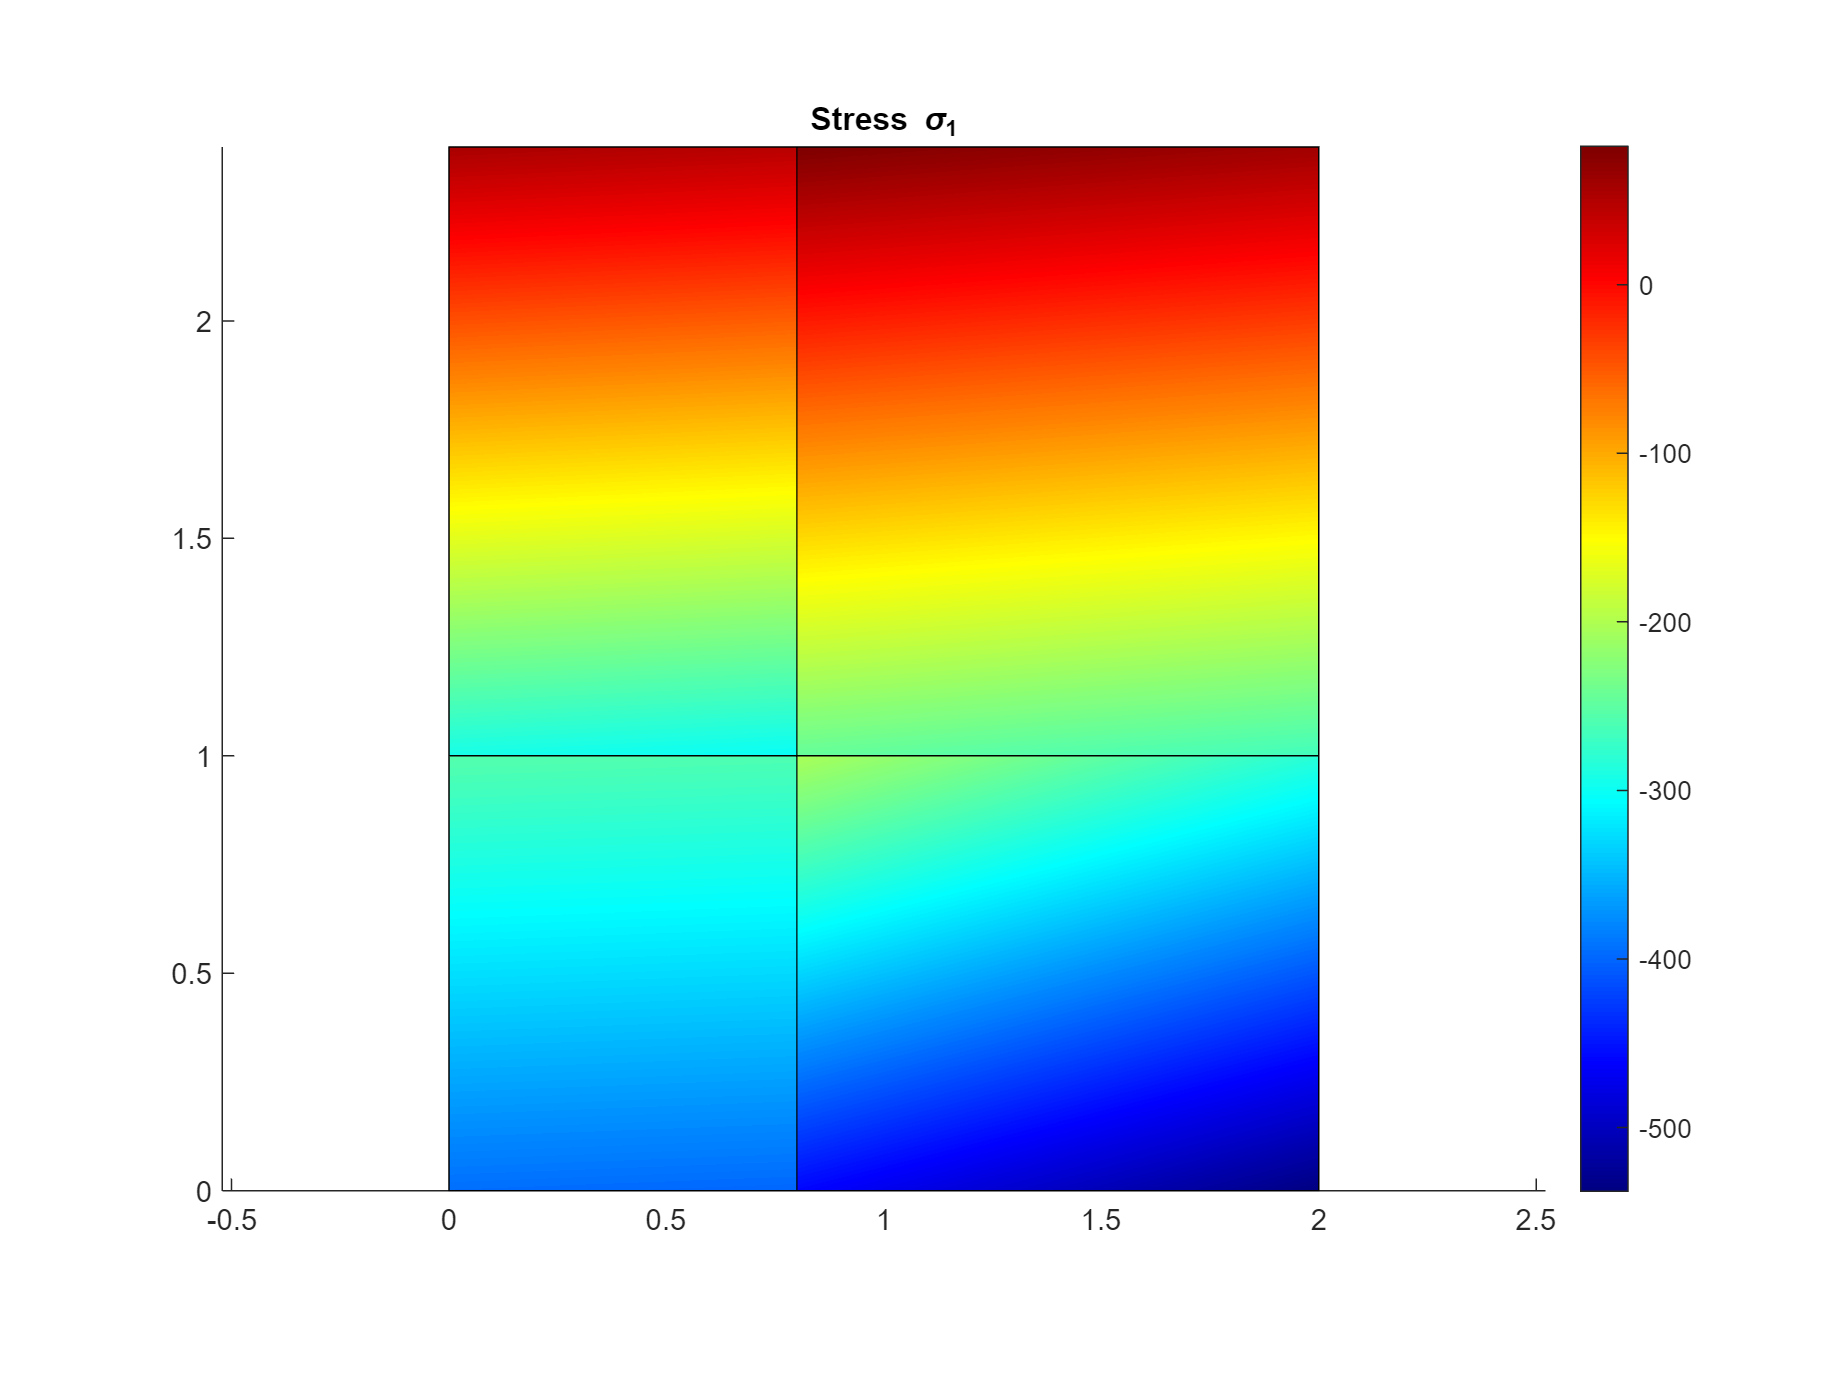

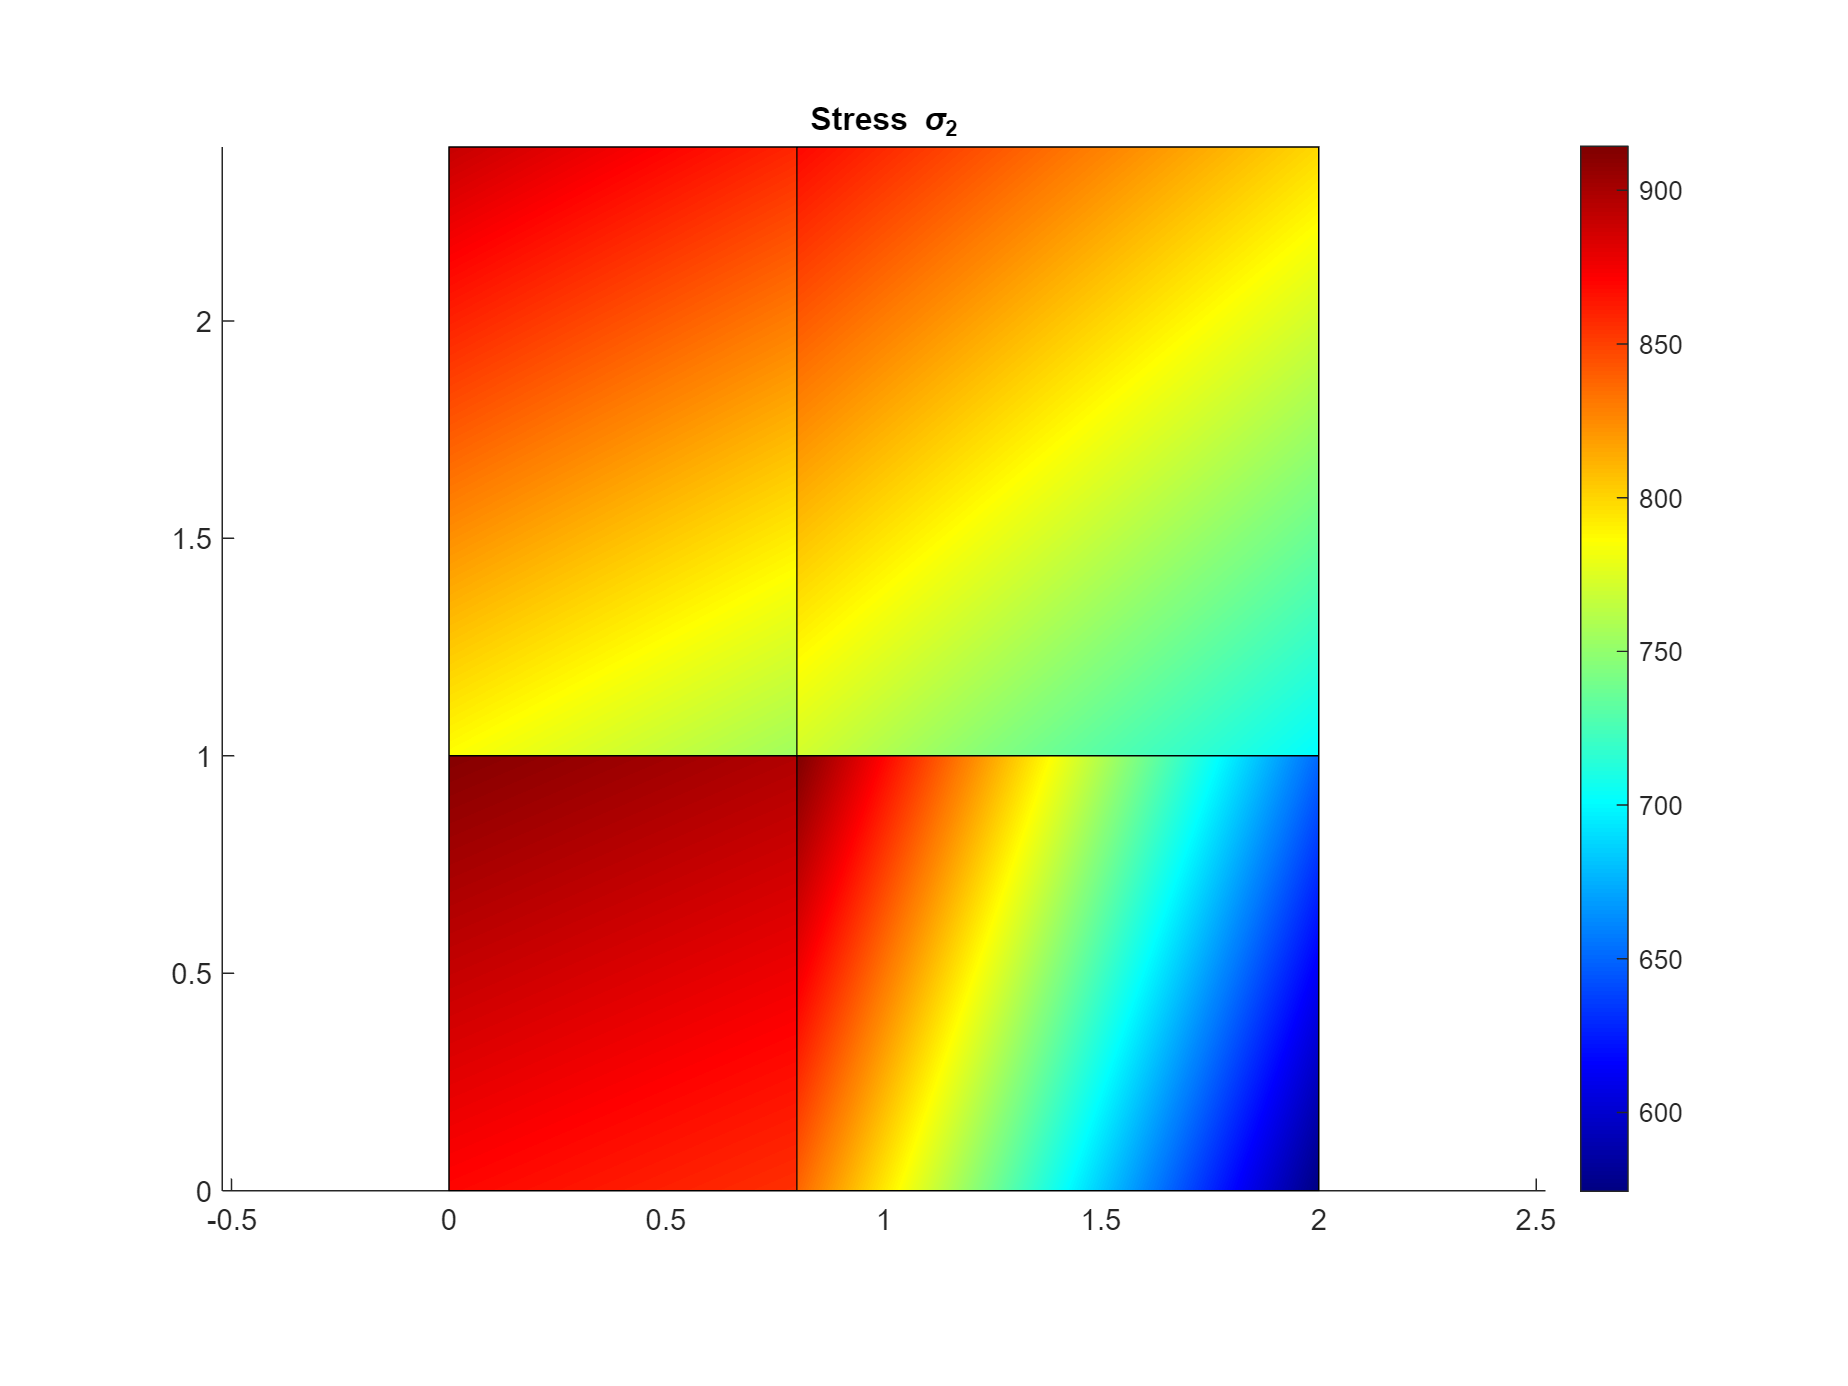

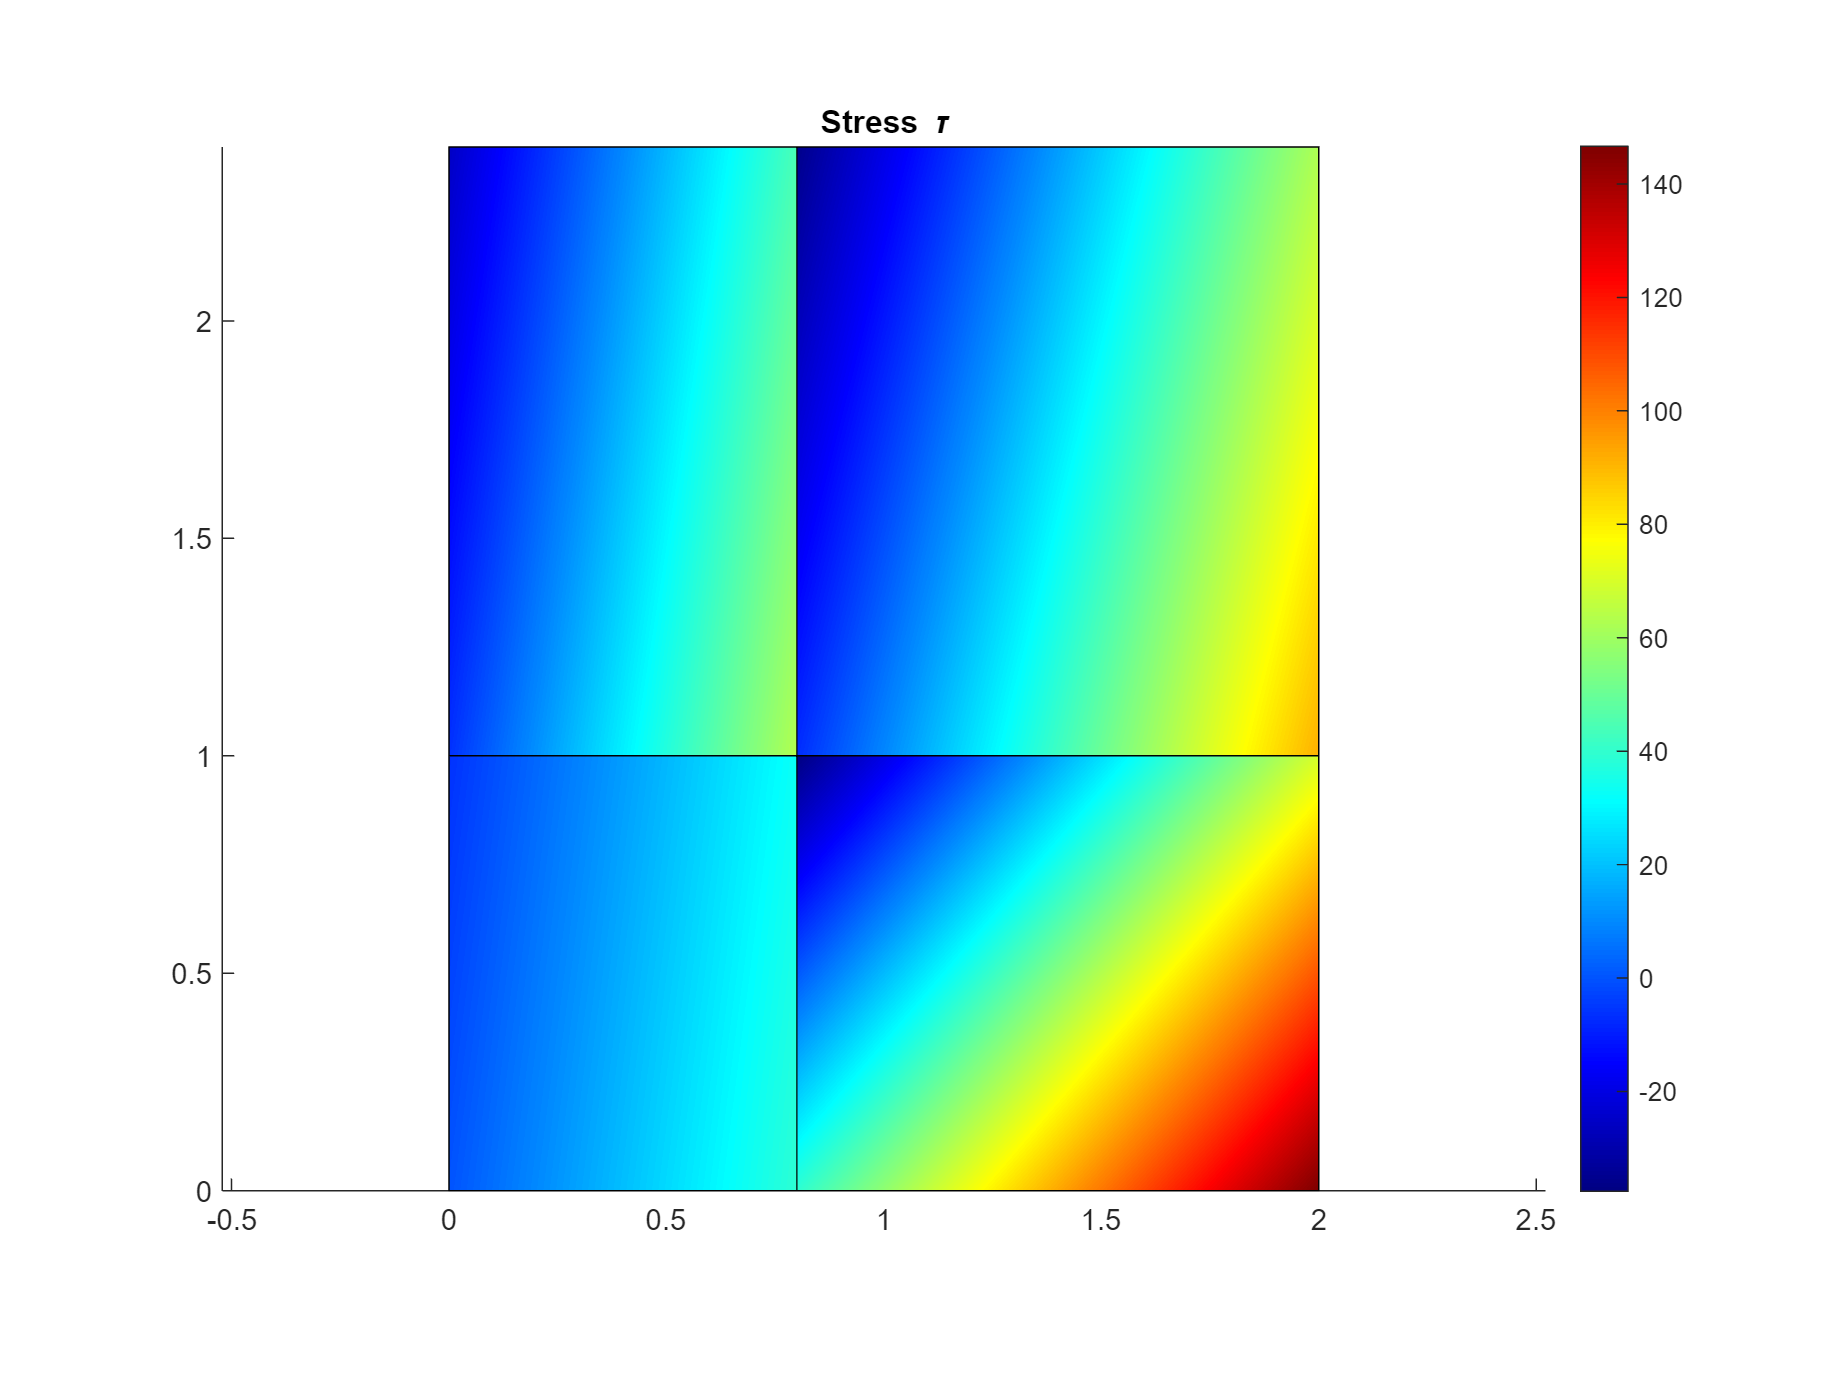

% Prepare plots
patchesSigma1 = plotElements(nodes, elements, 'Stress \sigma_1');
patchesSigma2 = plotElements(nodes, elements, 'Stress \sigma_2');
patchesSigma12 = plotElements(nodes, elements, 'Stress \tau');

% Initialize cells or arrays for stress
strainGauss = cell(nElements, 1);
stressGauss = cell(nElements, 1);
strainNodes = cell(nElements, 1);
stressNodes = cell(nElements, 1);
misesGauss = zeros(nElements, 4);
misesNodes = zeros(nElements, 4);

% Element-wise stress calculation
for e = 1 : nElements
    xmin = nodes(elements(e, 1), 1);
    xmax = nodes(elements(e, 3), 1);
    ymin = nodes(elements(e, 1), 2);
    ymax = nodes(elements(e, 3), 2);

    indices = [2 * elements(e, :) - 1; 2 * elements(e, :)];
    indices = indices(:);

    % Compute stress at integration points
    strainGauss{e} = zeros(4, 3);
    stressGauss{e} = zeros(4, 3);
    for g = 1 : size(xg, 1)
        % Map integration point from standard space (r, s) to cartesian coordinates (x, y)
        xgi(1) = 0.5 * (xmax - xmin) * xg(g, 1) + 0.5 * (xmax + xmin);
        xgi(2) = 0.5 * (ymax - ymin) * xg(g, 2) + 0.5 * (ymax + ymin);

        % Get B matrix for stress calculation
        B = bMatrix(xmin, xmax, ymin, ymax, xgi);

        % Evaluate stress at INTEGRATRION points
        strainGauss{e}(g, :) = B * u(indices);
        stressGauss{e}(g, :) = C * B * u(indices);

        % Compute von Mises stress at integration point
        misesGauss(e, g) = vonMisesStress(stressGauss{e}(g, :));
    end

    % Compute stress at nodes
    strainNodes{e} = zeros(4, 3);
    stressNodes{e} = zeros(4, 3);
    elementNodes = nodes(elements(e, :), :);
    for g = 1 : size(elementNodes, 1)
        % Get B matrix for stress calculation
        B = bMatrix(xmin, xmax, ymin, ymax, elementNodes(g, :));

        % Evaluate stress at NODES
        strainNodes{e}(g, :) = B * u(indices);
        stressNodes{e}(g, :) = C * B * u(indices);
    end
    % Compute von Mises stress at nodes in one go
    misesNodes(e, :) = vonMisesStress(stressNodes{e});

    % patch interpolates linearly between the given values of the edges
    patchesSigma1(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodes{e}(:, 1));
    patchesSigma1(e).FaceAlpha = 1;
    patchesSigma2(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodes{e}(:, 2));
    patchesSigma2(e).FaceAlpha = 1;
    patchesSigma12(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodes{e}(:, 3));
    patchesSigma12(e).FaceAlpha = 1;
end

% Averaging nodal stress
stressAvg = zeros(nNodes, 3);

stressAvg(1, :) = stressNodes{1}(1, :);
stressAvg(2, :) = 1/2 * (   stressNodes{1}(2, :) + ...
                            stressNodes{2}(1, :));
stressAvg(3, :) = stressNodes{2}(2, :);
stressAvg(4, :) = 1/2 * (   stressNodes{1}(4, :) + ...
                            stressNodes{3}(1, :));
stressAvg(5, :) = 1/4 * (   stressNodes{1}(3, :) + ...
                            stressNodes{2}(4, :) + ...
                            stressNodes{3}(2, :) + ...
                            stressNodes{4}(1, :));
stressAvg(6, :) = 1/2 * (   stressNodes{2}(3, :) + ...
                            stressNodes{4}(2, :));
stressAvg(7, :) = stressNodes{3}(3, :);
stressAvg(8, :) = 1/2 * (   stressNodes{3}(3, :) + ...
                            stressNodes{4}(4, :));
stressAvg(9, :) = stressNodes{4}(3, :);

% Averaging von Mises stress
%   If we want to compute the von Mises stress at the nodes, the question about the order of computations
%   arises. We could 
%               1. compute the nodal stress for each element, 
%               2. average the nodal stresses and 
%               3. then compute the von Mises stress from the averaged nodal stress. 
% 
%               On the other hand, we could 
%               1. first compute the nodal von Mises stress for each element and 
%               2. then average the von Mises stress, similar as for the nodes. 

misesAvg = zeros(nElements, 1);

% Mises Avg NODES
misesAvg(1) = 1/4 * sum(misesNodes(1, :));
misesAvg(2) = 1/4 * sum(misesNodes(2, :));
misesAvg(3) = 1/4 * sum(misesNodes(3, :));
misesAvg(4) = 1/4 * sum(misesNodes(4, :));
misesAvg

misesAvg =   600.0674
  701.1724
  308.5807
  278.0197


% Mises Avg GAUSS
misesAvg(1) = 1/4 * sum(misesGauss(1, :));
misesAvg(2) = 1/4 * sum(misesGauss(2, :));
misesAvg(3) = 1/4 * sum(misesGauss(3, :));
misesAvg(4) = 1/4 * sum(misesGauss(4, :));
misesAvg

misesAvg = 1.0e+03 *

    1.0859
    0.9926
    0.8958
    0.8420


misesGauss

misesGauss = 1.0e+03 *

    1.1054    1.1005    1.0662    1.0716
    1.0758    0.9861    0.9008    1.0077
    0.9319    0.9210    0.8584    0.8719
    0.8818    0.8569    0.7993    0.8300


misesNodes

misesNodes =   600.0674  600.0674  600.0674  600.0674
  701.1724  701.1724  701.1724  701.1724
  308.5807  308.5807  308.5807  308.5807
  278.0197  278.0197  278.0197  278.0197


1/4 * ( vonMisesStress(stressAvg(1,:)) + ...
        vonMisesStress(stressAvg(2,:)) + ...
        vonMisesStress(stressAvg(4,:)) + ...
        vonMisesStress(stressAvg(5,:)))

ans = 1.0617e+03

vonMisesStress(1/4 * (  (stressAvg(1,:)) + ...
                        (stressAvg(2,:)) + ...
                        (stressAvg(4,:)) + ...
                        (stressAvg(5,:))))

ans = 1.0601e+03

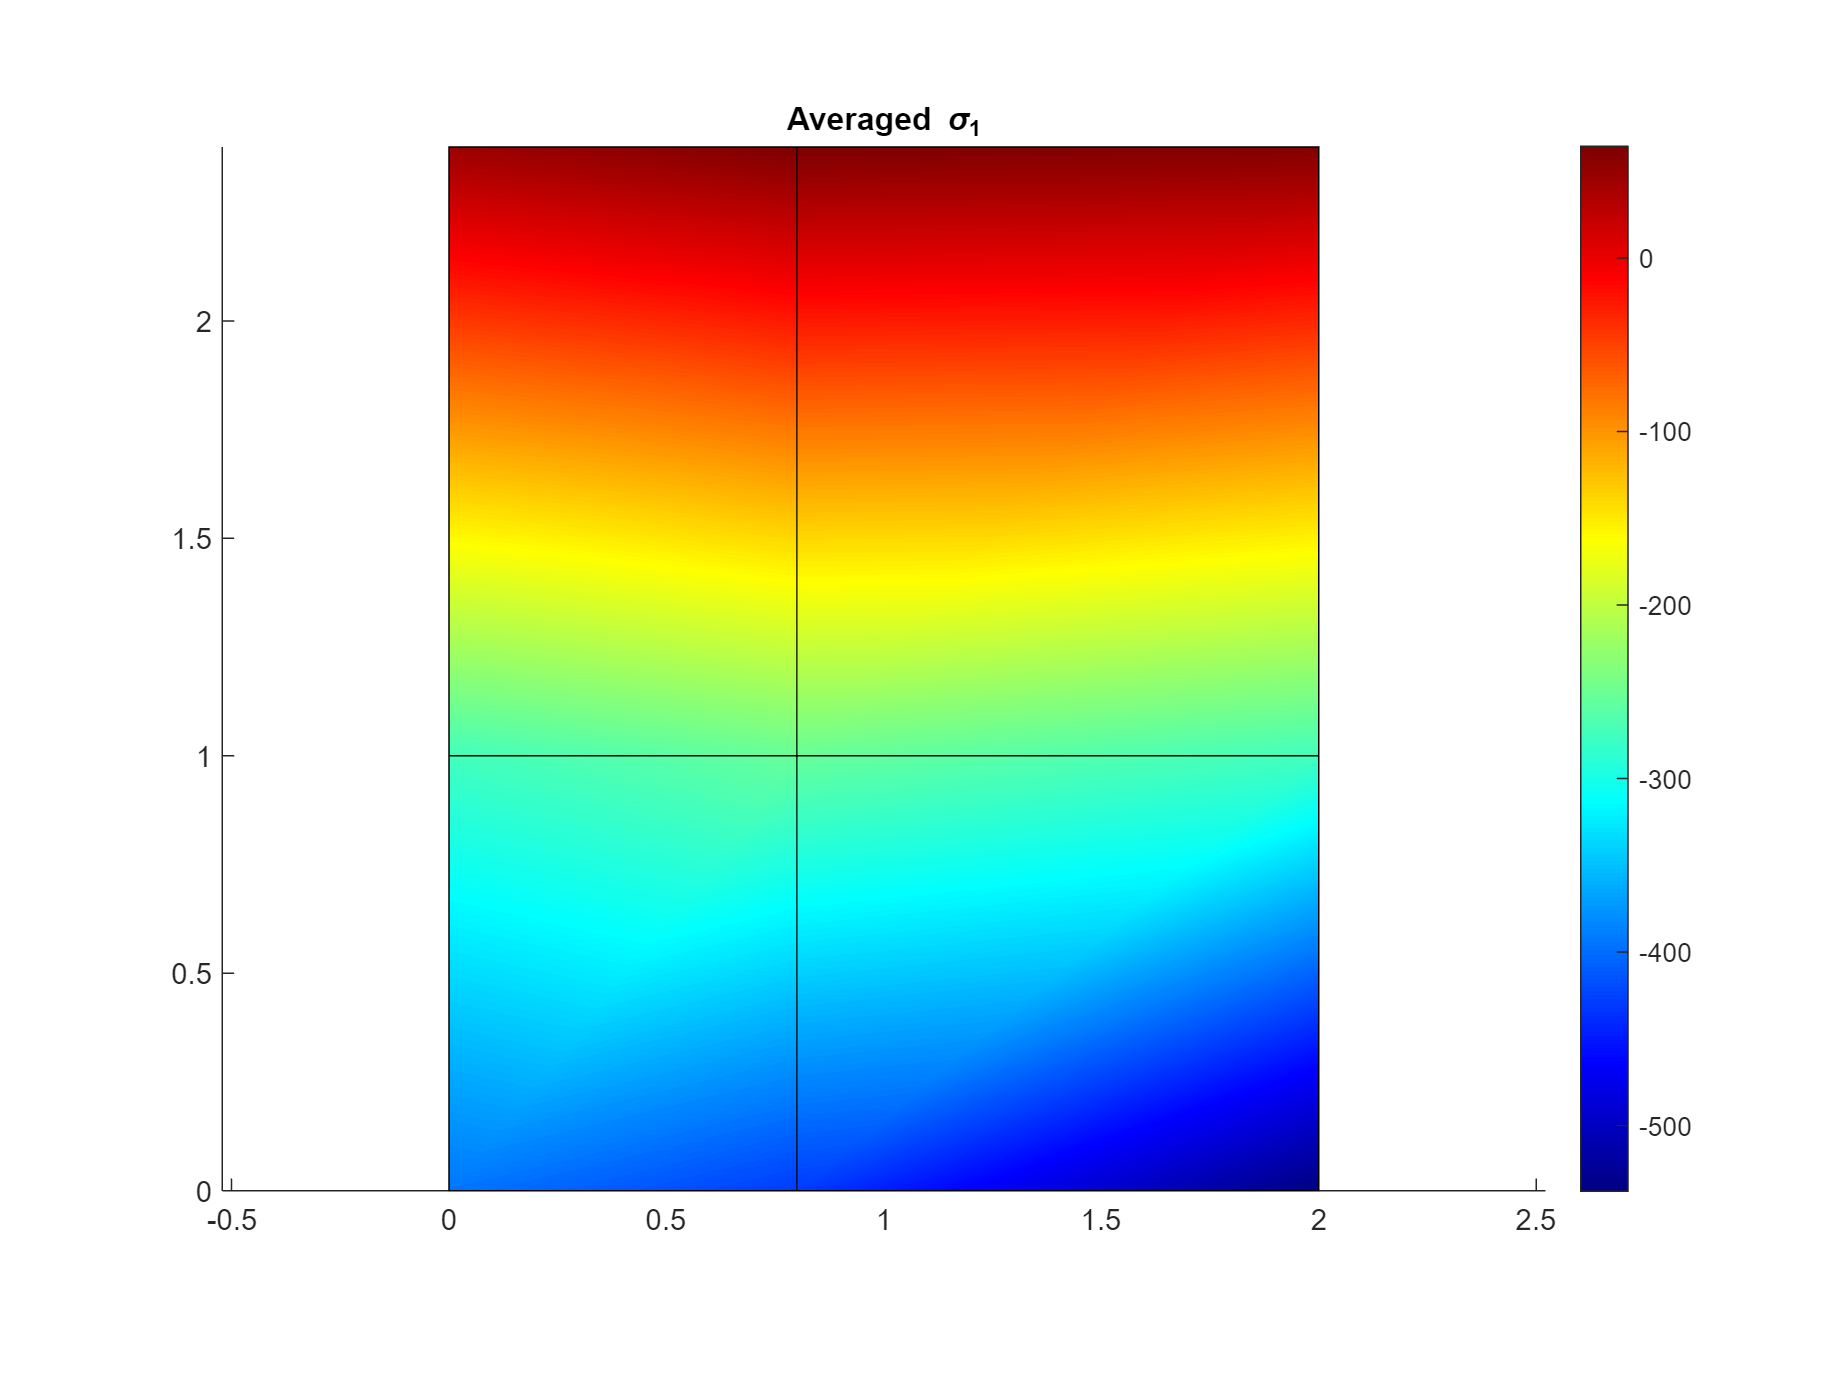

plotElements(nodes, elements, 'Averaged \sigma_1', stressAvg(:, 1));

function h = shapeFunctions(xmin, xmax, ymin, ymax, x)
    % Evaluate shape functions for rectangular element at x in cartesian coordinates
    % INPUT
    %   xmin (scalar)       Minimum x coordinate for element
    %   xmax (scalar)       Maximum x coordinate for element
    %   ymin (scalar)       Minimum y coordinate for element
    %   ymax (scalar)       Maximum y coordinate for element
    %   x (array)           Point(s) for evaluation of shape functions in cartesian coordinates

    A = (xmax - xmin) * (ymax - ymin);

    % Evaluate shape functions
    h(:, 1) = 1/A * (xmax - x(:, 1)) .* (ymax - x(:, 2));
    h(:, 2) = 1/A * (x(:, 1) - xmin) .* (ymax - x(:, 2));
    h(:, 3) = 1/A * (x(:, 1) - xmin) .* (x(:, 2) - ymin);
    h(:, 4) = 1/A * (xmax - x(:, 1)) .* (x(:, 2) - ymin);
end

function dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, x)
    % Evaluate shape functions gradients for rectangular element at x in cartesian coordinates
    % INPUT
    %   xmin (scalar)       Minimum x coordinate for element
    %   xmax (scalar)       Maximum x coordinate for element
    %   ymin (scalar)       Minimum y coordinate for element
    %   ymax (scalar)       Maximum y coordinate for element
    %   x (array)           Point(s) for evaluation of shape functions in cartesian coordinates

    A = (xmax - xmin) * (ymax - ymin);

    dh(1:2, 1) = -1/A * [(ymax - x(2)) ; (xmax - x(1))];
    dh(1:2, 2) = 1/A * [(ymax - x(2)); (-(x(1) - xmin))];
    dh(1:2, 3) = 1/A * [(x(2) - ymin); ((x(1) - xmin))];
    dh(1:2, 4) = -1/A * [(x(2) - ymin); -(xmax - x(1))];
end

function H = hMatrix(xmin, xmax, ymin, ymax, x)
    % Evaluate H matrix for linear quadrilaterial element
    % INPUT
    %   xmin (scalar)   Minimum x coordinate for element
    %   xmax (scalar)   Maximum x coordinate for element
    %   ymin (scalar)   Minimum y coordinate for element
    %   ymax (scalar)   Maximum y coordinate for element
    %   x (array)       Point(s) for evaluation of shape functions in cartesian coordinates
    % OUTPUT
    %   H (array)       H matrix for linear quadrilateral element

    H = [];
end

function B = bMatrix(xmin, xmax, ymin, ymax, x)
    % Evaluate H matrix for linear quadrilaterial element
    % INPUT
    %   xmin (scalar)   Minimum x coordinate for element
    %   xmax (scalar)   Maximum x coordinate for element
    %   ymin (scalar)   Minimum y coordinate for element
    %   ymax (scalar)   Maximum y coordinate for element
    %   x (array)       Point(s) for evaluation of shape functions in cartesian coordinates
    %                       x and y
    % OUTPUT
    %   B (array)       B matrix for linear quadrilateral element

    % dh 2x4: derivatives of shape fuunctions
    dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, x);

    % B matrix given on slide 9&10
    %   first B matrix          second                  third                   forth 
    B = [dh(1,1),   0,          dh(1,2),    0,          dh(1,3),    0,          dh(1,4),    0;
         0,         dh(2,1),    0,          dh(2,2),    0,          dh(2,3),    0,          dh(2,4);
         dh(2,1),   dh(1,1),    dh(2,2),    dh(1,2),    dh(2,3),    dh(1,3),    dh(2,4),    dh(1,4)];
end

% Mises
function mises = vonMisesStress(stress)
    % Compute mises stress from given stress vector in voigt notation
    % INPUT
    %   stress (array)          Stress vector(s) as row vector
    % OUTPUT
    %   mises (scalar/array)    von Mises stress for each row of stress input array
    
    mises = sqrt(   stress(1).^2 + ...
                    stress(2).^2 - ...
                    stress(1) * stress(2) + ...
                    3 * stress(3)^2);
end

% Field functions

% These are functions to evaluate quantities either by interpolating from nodal values or 
% directly calculating the stress component at a given position.

function u = field(xmin, xmax, ymin, ymax, x, y, nodalValues)
    % Interpolate nodal values to given location
    % INPUT
    %   xmin (scalar)   Minimum x coordinate for element
    %   xmax (scalar)   Maximum x coordinate for element
    %   ymin (scalar)   Minimum y coordinate for element
    %   ymax (scalar)   Maximum y coordinate for element
    %   x (array)       x coordinate(s) for evaluation of shape functions in cartesian coordinates
    %   y (array)       y coordinate(s) for evaluation of shape functions in cartesian coordinates
    % OUPUT
    %   u (scalar)      Interpolated quantity

    u = zeros(size(x));
    H = shapeFunctions(xmin, xmax, ymin, ymax, [x(:), y(:)]);
    for i = 1 : numel(u)
        u(i) = H(i, :) * nodalValues;
    end
    % u = reshape(u, size(x));
end

function s = stressField(xmin, xmax, ymin, ymax, x, y, C, u, component)
    % Compute stress tensor at location x and return specific component
    % INPUT
    %   xmin (scalar)       Minimum x coordinate for element
    %   xmax (scalar)       Maximum x coordinate for element
    %   ymin (scalar)       Minimum y coordinate for element
    %   ymax (scalar)       Maximum y coordinate for element
    %   x (array)           x coordinate(s) for evaluation of stress
    %   y (array)           y coordinate(s) for evaluation of stress
    %   C (array)           Stress-strain or constitutive matrix
    %   u (array)           Vector of nodal displacements
    %   component (scalar)  0: Mises, 1: sigma_x, 2: sigma_y, 3: sigma_xy
    % OUPUT
    %   s (scalar/array)    Stress value(s) for given location

    s = zeros(size(x));
    for i = 1 : numel(s)
        B = bMatrix(xmin, xmax, ymin, ymax, [x(i), y(i)]);
        stress = C * B * u;
        if component == 0
            % Mises
            s(i) = vonMisesStress(stress');
        else
            s(i) = stress(component);
        end
    end
end

% Plot functions
function p = plotElements(nodes, elements, title, color)
    % Plot elements by plotting a patch for each element
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   color (array)       OPTIONAL: Color for nodes or elements per row
    % OUTPUT
    %   p (array)           Patches for elements

    newFigure(title);
    hold on;
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);
        p(e) = patch(elementNodes(:, 1), elementNodes(:, 2), 'w');
        if nargin > 3
            if size(color, 1) == size(nodes, 1)
                % Interpolate between nodal values
                p(e).set('FaceColor', 'interp', 'FaceVertexCData', color(elements(e, :)));
            elseif size(color, 1) == size(elements, 1)
                % Color per element
                p(e).set('FaceColor', 'flat', 'FaceVertexCData', color(e));
            end
            clim([min(color), max(color)]);
            % p(e).EdgeAlpha = 0;
        else
            p(e).FaceAlpha = 0;
        end
    end
    hold off;
end

function plotStressField(nodes, elements, C, u, component, title)
    % Plot stress field for given component
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   C (array)           Stress-strain or constitutive material matrix
    %   u (array)           Vector of nodal displacements of size (DOF x 1)
    %   component (scalar)  Stress component for plotting
    %   title (char)        Title for plot

    newFigure(title);
    hold on;
    for e = 1 : 3
        xmin = nodes(elements(e, 1), 1);
        xmax = nodes(elements(e, 3), 1);
        ymin = nodes(elements(e, 1), 2);
        ymax = nodes(elements(e, 3), 2);
        indices = [2 * elements(e, :) - 1; 2 * elements(e, :)];
        indices = indices(:);
        fhStress = @(x, y) stressField(xmin, xmax, ymin, ymax, x, y, C, u(indices), component);
        fsurf(fhStress, [xmin xmax ymin ymax], 'LineStyle', 'none');
    end
    hold off;
    view(2)
    xlim([min(nodes(:,1)), max(nodes(:,1))]);
    ylim([min(nodes(:,2)), max(nodes(:,2))]);
end

function plotField(nodes, elements, nodalValues, title)
    % Plot field by interpolating between nodal values
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   nodalValues (array) Nodal values for interpolation and plotting
    %   title (char)        Title for plot

    newFigure(title);
    hold on;
    for e = 1 : 3
        xmin = nodes(elements(e, 1), 1);
        xmax = nodes(elements(e, 3), 1);
        ymin = nodes(elements(e, 1), 2);
        ymax = nodes(elements(e, 3), 2);
        fhf = @(x, y) field(xmin, xmax, ymin, ymax, x, y, nodalValues(elements(e, :)));
        fsurf(fhf, [xmin xmax ymin ymax], 'LineStyle', 'none');
    end
    hold off;
    view(2)
    xlim([min(nodes(:,1)), max(nodes(:,1))]);
    ylim([min(nodes(:,2)), max(nodes(:,2))]);
    clim([min(nodalValues), max(nodalValues)])
end

function f = newFigure(figureTitle)
    % Open figure and set several common options
    % INPUT
    %   figureTitle (string/char array)     OPTIONAL: title for figure
    % OUTPUT
    %   f (figure) 

    f = figure;
    f.Position([3, 4]) = 1.5 * f.Position([3, 4]);
    f.Position(2) = f.Position(2) - f.Position(4)/3;
    axis equal; 
    colormap jet;
    colorbar;
    if nargin > 0
        title(figureTitle);
    end
end